# 9.30.25 - Roots: Open Methods

## Problem 6.3

Determine the highest real root of f(x) = x^3-6*x^2+11*x-6.1

a. Graphicallly

b. Newton's method (Newton-Raphson, 3 iter, x0 = 3.5)

c. Secant (3 iter, x^-1 = 2.5, x0=3.5)

d. Modified secant (3 iter, x^-1 = 2.5, delta=0.01)d

#### Graphical method

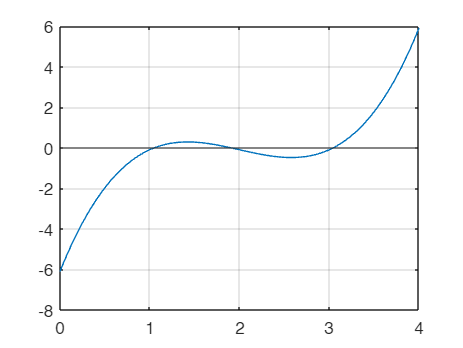

x = linspace(0,4);
y = x.^3-6*x.^2+11.*x-6.1;
plot(x,y);
grid on;
hold on;
yline(0);
hold off;

% look for the intersections

#### Newton-Raphson

% derivative to function handle *********
syms x
f_sym = x^3 - 6*x^2 + 11*x - 6.1;   % symbolic function
df_sym = diff(f_sym, x);           % take derivative
func = matlabFunction(f_sym);
dfunc = matlabFunction(df_sym);    % convert to function handle


xr = 0; es =0.00001; maxit = 3;
[root_nr,ea_nr,iter_nr]=newtraph(func,dfunc,xr,es,maxit)

root_nr = 1.0167

ea_nr = 14.1913

iter_nr = 3


% newtraph: Newton-Raphson root location zeroes
% [root,ea,iter]=newtraph(func,dfunc,xr,es,maxit,p1,p2,...):
% uses Newton-Raphson method to find the root of func
% input:
%   func = name of function
%   dfunc = name of derivative of function
%   xr = initial guess
%   es = desired relative error (default = 0.0001%)
%   maxit = maximum allowable iterations (default = 50)
%   p1,p2,... = additional parameters used by function
% output:
%   root = real root
%   ea = approximate relative error (%)
%   iter = number of iterations

#### Secant Method